## Checking the transfer function

We first import the transfer function generated in step004. We plot a step response generated with this transfer function, just so we can visually compare it to the recorded data, thus making sure we are treating the right system. 

clear all;
close all;
load("../../step004-identify-transfer-function/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
tData= identifyTransferFunctionContinuousTimeResults.tData;
yDeg= identifyTransferFunctionContinuousTimeResults.yData;

Let"s plot the open-loop transfer function again for completeness. Recall the transfer function has the form

 $\[
G_S(s)= \frac{K_S}{s^2+ a_1 s+ a_0}
\]$,

where we are now using the standard form with coefficients $a_i$ and $b_i$ for convenience. The corresponding differential equation reads

$\ddot{\varphi} +a_1 \dot{\varphi} +\varphi =K_S u$.

We can read the gain $K_S$ and coefficients $a_1$ and $a_0$ off the transfer function found from the experimental data:

GS= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
GS

GS =
  From input "u1" to output "y1":
         -9076
  -------------------
  s^2 + 28.8 s + 8769
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "identData".
Fit to estimation data: 87.91%                        
FPE: 0.02159, MSE: 0.01955                            
 
Model Properties


Let's plot the step response to visually check that we are treating the expected transfer function.

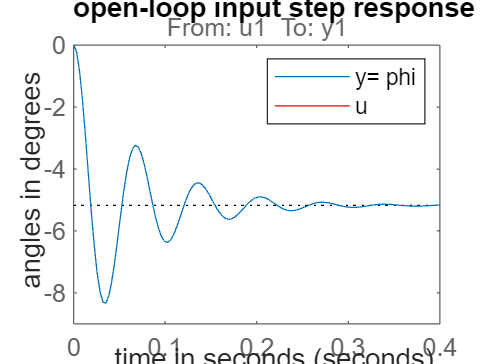

figure();
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(GS, stepOpt); 
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 
title("open-loop input step response");
hold off; 

## Closed-loop with PID controller

### Transfer function of the closed loop

We now introduce a controller and close the loop around our system with differential equation $\ddot{\varphi} +a_1 \dot{\varphi} +\varphi =K_S u$.

The closed loop is shown in the following diagram. Make sure you find the output $y$, the reference value $r$, the error $e=r-y$ and the input $u$ generated by the controller in the diagram.   

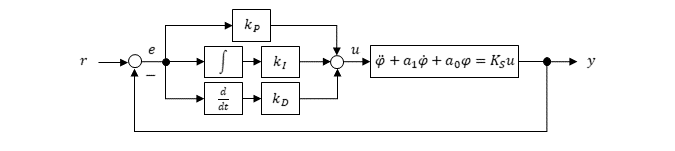

The controller is a PID controller ("proportional–integral–derivative" controller). It is called PID controller, because it adds a signal that is proportional to 

- the error $e=y-r$ (proportionality constant $k_P$), 

- the integral of $e$ (multiplied by constant $k_I$, center arc in the controller block), and 

- the derivative of $e$ (multiplied by constant $k_D$, bottom arc in the controller block in the diagram).  

The differential equation that corresponds to block diagram reads as follows. Make sure you recognize all blocks of the PID controller in the differential equation again:


$$\ddot{\varphi} +a_1 \dot{\varphi} +a_0 \varphi =K_S \left(k_P \left(r-\varphi \right)+k_I \int_0^t \left(r\left(\tau \;\right)-\varphi \left(\tau \;\right)\right)d\tau \;+k_D \frac{d}{\textrm{dt}}\left(r\left(t\right)-\varphi \left(t\right)\right)\right)$$


It is convenient to treat this system in the frequency space. Recall the output is $y=\varphi$ and let $Y$ refer to its Laplace-transform. Let $U$and $R$ refer to the transforms of $u$ and $r$, respectively. The transfer function $G_S=\frac{K_S}{s^2+ a_1 s+ a0}$ of the second order differential equation $\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_Su$ was already stated above.

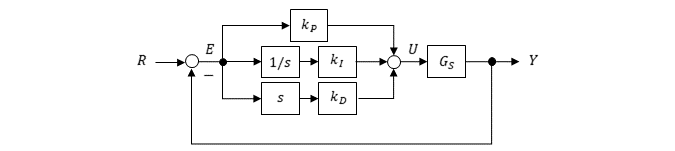

Laplace-transforming the differential equation of the block diagram yields

$s^2 Y+a_1 \textrm{sY}+a_0 Y=K_S \left(k_P +\frac{k_I }{s}+sk_D \right)\left(R-Y\right)$,

where we assume all initial conditions to be zero. Multiplying both sides by $s$ and rearranging terms then yields the closed-loop transfer function 

$G_{cl}=\frac{Y}{R}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}$.

### Pole placement: Idea and equations

Recall the poles of a transfer function (i.e., the zeros of its numerator) reveal if the system modeled by the transfer function is stable. More precisely, the system is asymptotically stable if all poles have negative real parts (here "negative" excludes the value zero). Moreover, 

- the real parts of the poles determine how fast the system converges to a steady state (the more negative, the faster), and 

- the imaginary parts determine the frequencies of oscillations (in particular, no oscillations can occur if all imaginary parts are zero). 

"Pole placement" refers to the following idea: While the poles of our system transfer function are given by the physical properties of the system, we can try to set the poles of the closed-loop sysem (i.e., the poles of $G_{cl}$ above) to desired values. We can try to do so by adjusting the controller constants $k_P$, $k_I$, $k_D$ (Have a look at the diagram to find them again!).  

Note that our closed-loop transfer function $G_{cl}$ has a third order denominator. This implies it has 3 poles. Roughly speaking, setting these 3 poles to desired values fixes the three controller constants $k_P$, $k_I$, $k_D$. We have to analyze the denominator more carefully, however, since we may not be able to generate arbitrary poles even though the number of poles and adjustable constants is equal.  

Let's denote the three poles by $s_1$, $s_2$, $s_3$. Below we try to achieve, for example, $s_1= -100$, $s_2=-101$, $s_3= -102$, which implies

- stability (all three $s_i$ have negative real parts), 

- fast decay ($\exp(-100 t)$ decays to $1/e\approx 0.37$ in $1/100$s)  

- and no oscillations (all imaginary parts are zero).

In order to find the equations that determine $k_P$, $k_I$, and $k_D$ for given values $s_1$, $s_2$ and $s_3$ we set $G_\rm{cl}$ equal to the transfer function with the desired poles:

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}$.

This equality obviously holds if the denominators are equal, i.e.,

$s^3+(a_1+K_S k_D)s^2+ (a_0+K_S k_P)s+K_S k_I= (s-s_1)(s-s_2)(s-s_3)$.

Expanding the right hand side yields


$$s^3+(a_1+K_S k_D)s^2+ (a_0+K_S k_P)s+K_S k_I= s^3 + (-s_1 - s_2 - s_3) s^2 + (s_1 s_2 + s_1 s_3 + s_2 s_3) s - s_1 s_2 s_3$$


and by comparing coefficients we find the three conditions

$a_1+ K_S k_D= -s_1-s_2-s_3$, 

$a_0+K_S k_P=s_1 s_2+ s_1 s_3+ s_2 s_3$, 

$K_S k_I= -s_1 s_2 s_3$.

These equations can be solved for $k_P$, $k_I$, $k_D$. This yields

$k_P = -(-s_1 s_2 - s_1 s_3 - s_2 s_3 + a_0)/K_S$,

$k_D = -(a_1 + s_1 + s_2 + s_3)/K_S$,

$k_I = -s_1 s_2 s_3/K_S$.

Make sure you understand this result: For the transfer function found from data (with constants $a_0$, $a_1$, $K_S$ adjusted to fit the data) we close the loop with a controller with tuning parameters $k_P$, $k_I$, $k_D$. We then choose poles $s_1$, $s_2$, $s_3$ that we would like to result for the closed loop system and determine $k_P$, $k_I$ and $k_D$ with the formulas above. 

### Pole placement: Application to our example

We first need to extract the coefficients $a_0$, $a_1$, $a_2$ and $K_S$ from our open-loop transfer function. Note that $a_2$ was $1$ so far. We include $a_2$ here for completeness and throw an error if it is not $1$.

G= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
K= G.Numerator;
a2= G.Denominator(1); 
a1= G.Denominator(2);
a0= G.Denominator(3);
if(a2~=1) 
    error("expecting a2= 1");
end

We choose the desired poles in the next step:

continuousTimePoles= [-51, -50, -52];
s1= continuousTimePoles(1);
s2= continuousTimePoles(2);
s3= continuousTimePoles(3);

Now we are ready to evaluate pole placement equations derived above. 

kP= -(-s1 * s2 - s1 * s3 - s2 * s3 + a0) / K;
kD= -(a1 + s1 + s2 + s3) / K;
kI= -s1 * s2 * s3 / K;

We can now create the controller transfer function `GR` and the closed-loop transfer function `Gcl`. It then only remains to plot the step response of the closed loop to see if our controller works:

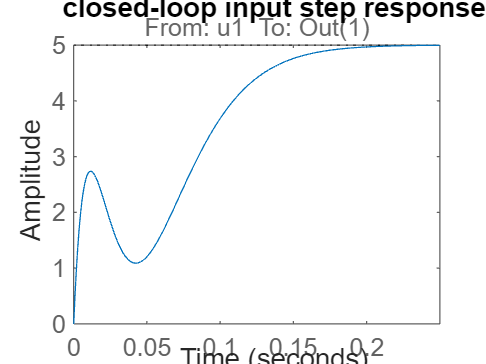

GR= tf([kD, kP, kI], [1, 0]);
Gcl= feedback(GR* G, 1);
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(Gcl, stepOpt); 
title("closed-loop input step response");

The system reaches the new steady state in about 1/10 of a second. It does not oscillate (for an oscillation it would have to swing to values larger than 5 degrees), but it wiggles. (It is not monotonic.) The disturbance rejection also suffers from the wiggling motion. Recall the disturbance rejection is described by the transfer function `1/(1+G*GR)`:

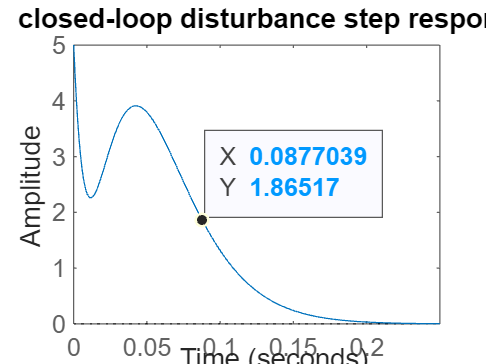

step(1/(1+GR* G), stepOpt)
title("closed-loop disturbance step response");

This plot tells us how a disturbance by 5 degrees, which can be generated by picking up the gimbal and turning by 5 degrees by hand, is "rejected", i.e., how the controller moves the gimbal back by 5 degrees to compensate the motion applied by hand.

Let's print the values of the controller parameters $k_P$, $k_I$ and $k_D$ for use in future arduino sketches.

kP

kP = 0.1066

kI

kI = -14.6095

kD

kD = -0.0137

## Closed loop with smoother (but slower) PID controller

In this section, we try to improve the PID controller constructed above. The section is already quite **advanced** for students who have not yet completed their first semester control course. 

### Idea

We expect the step response of a third order transfer function

$G_{\mathrm{helper}}=\frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}$.

for three real poles, e.g. $s_1= -100$, $s_2= -101$, $s_3= -102$ **not to have the non-monotonic, wiggling behaviour** found in the pole placement result for the PID controller above. We expect this, because $G_\textrm{helper}$ can be understood to result from a series connection of three first order transfer functions, i.e.

$G_\textrm{helper}= K_\textrm{helper}\frac{1}{s-s_1} \cdot \frac{1}{s-s_2} \cdot \frac{1}{s-s_3}$.

Let's check the step response of $G_\textrm{helper}$ by plotting it. Expanding the transfer function $G_{\mathrm{helper}}$ yields

$G_{\mathrm{helper}}= \frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}= \frac{K_\textrm{helper}}{s^3 + (-s_1 - s_2 - s_3) s^2 + (s_1 s_2 + s_1 s_3 + s_2 s_3) s - s_1 s_2 s_3}$.

The form on the right hand side is convenient for use with matlab's `tf()` command for the construction of transfer functions. The next code snippet plots the unit step response for $G_\text{helper}$. (Note that we need to set $K_\textrm{helper}$ so that the steady-state gain of $G_\textrm{helper}$ is 1 because we want the unit step response to attain 1 for $t\rightarrow\infty$. This yields $K_\textrm{helper}= \lim_{s\rightarrow 0} G_\textrm{helper}(s)= -s_1 s_2 s_3$.)

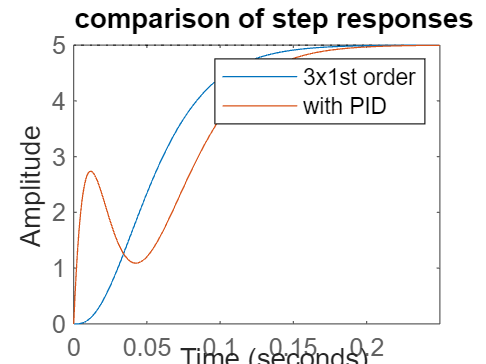

figure();
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(tf(-s1*s2*s3, [1 -s1-s2-s3 s1*s2+s1*s3+s2*s3 -s1*s2*s3]), stepOpt)
hold on;
step(Gcl, stepOpt); 
title("comparison of step responses"); 
legend("3x1st order", "with PID"); 

### Applying the idea to $G_\textrm{cl}$

Compare $G_\textrm{helper}$ to $G_\textrm{cl}$, which both are repeated here for convenience: 

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}, \quad G_{\mathrm{helper}}=\frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}$.

A closed-loop transfer function of the form of $G_\textrm{helper}$ would obviously result, if we managed to remove the contributions $k_Ds^2$ and $k_P s$ from the numerator of $G_\textrm{cl}$. Setting $k_D$ and $k_P$ to zero **does not give the desired result**, because $k_D$ and $k_P$ also enter the numerator of $G_\textrm{cl}$. This is evident from the equation

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}$,

which is taken from the section on pole placement above and also repeated here for convenience. We can, however, adjust the control loop to keep the desired numerator and thus the desired poles


$$\frac{1}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=\frac{1}{(s-s_1)(s-s_2)(s-s_3)}$$


but remove $k_D s^2$ and $k_P s$ from the numerator, i.e. achieve the replacement

$K_S\cdot(k_D s^2+ k_P s+ k_I)\longrightarrow K_S k_I$. In other words, we would like to achieve the replacment

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}\longrightarrow K_S\frac{k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}= G_{\textrm{cl, new}}$.

It is easy to see how this replacement can be achieved by analyzing the differential equation with the original PID controller stated above, which is again repeated here for convenience. It reads


$$\ddot{\varphi} +a_1 \dot{\varphi} +a_0 \varphi =K_S \left(k_P \left(r-\varphi \right)+k_I \int_0^t \left(r\left(\tau \;\right)-\varphi \left(\tau \;\right)\right)d\tau \;+k_D \frac{d}{\textrm{dt}}\left(r\left(t\right)-\varphi \left(t\right)\right)\right)\ldotp$$


We first recall how this differential equation corresponds to $G_\mathrm{cl}$ (**step 1 **below). It is then easy to see how the differential equation must be altered to correspond to $G_\mathrm{cl, new}$ (**step 2**). Finally, we will see that the altered differential equation corresponds to a new closed-loop block diagram (**step 3**).

#### Step 1 

We first differentiate the differential equation to remove the integral. This yields

$\dddot{\varphi}+ a_1\ddot{\varphi}+ a_0 \dot{\varphi}= K_S\left(k_P (\dot{r}- \dot{\varphi})+ k_I(r-\varphi)+ k_D (\ddot{r}- \ddot{\varphi})\right)$.

By collecting terms we obtain

$\dddot{\varphi}+ (a_1+ K_S k_D)\ddot{\varphi}+ (a_0+K_S k_P) \dot{\varphi}+ K_S k_I \varphi= K_S\left(k_P \dot{r}+ k_I r+ k_D \ddot{r}\right)$,

and Laplace transforming with $y=\varphi$ and assuming zero initial conditions yields


$$s^3 Y+ (a_1+ K_S k_D)s^2 Y+ (a_0 K_S k_P) s Y+ K_S k_I Y= K_S k_D s^2 R+ K_S k_P s R+ K_S k_I R$$


or equivalently 

$\frac{Y}{R}= K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}$,

which is $G_\mathrm{cl}$.

#### Step 2

By going throuth the manipulations of step 1 backwards we see that removing $k_D s^2+ k_P s$ from the numerator of $G_\mathrm{cl}$ (but not altering anything else about $G_\mathrm{cl}$ is equivalent to replacing the right hand side of the differential equation by 


$$\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_S\left(k_P(r-\varphi)+ k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau+ k_D \frac{d}{dt} (r(t)- \varphi(t))\right)\longrightarrow\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_S\left(k_P(-\varphi)+ k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau+ k_D \frac{d}{dt} (- \varphi(t))\right).$$


Note that this means the proportial and differential terms apply to $\varphi$ (more precisely, to $-\varphi$) instead of to $r-\varphi$. The integral term, in contrast, still applies to $r-\varphi$. 

#### Step 3

Let us rewrite the differential equation with the new right hand side for convenience to read 


$$\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= \underbrace{k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau}_{=:\bar{u}}- \underbrace{\left(K_S k_P\,\varphi+ K_S k_D \frac{d}{dt} \varphi(t)\right)}_{=:\tilde{u}}.$$


 We can generate $\tilde{u}$ by applying the proportional and differential terms to $\varphi$ before the subtraction symbol that yields $r-\varphi$:

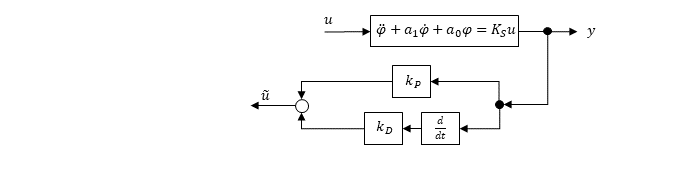

The signal $\bar{u}$ can be generated as before:

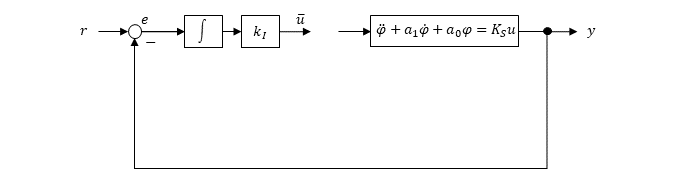

Combining $\bar{u}$ and $\tilde{u}$, taking the sign in front of $\tilde{u}$ into account, yields the new closed loop:

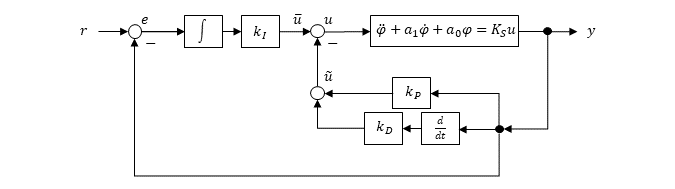

The resulting controller is not a PID controller anymore, because it does not merely add contributions proportional to $e=r-y$, the integral of $e$ and the derivative of $e$. The new structure is not more complicated, however, in that the same operations (integrating, forming derivatives, multiplying by proportionality constants) are required. 

### Implementing the new controller 

The new controller can be implemented by carrying out the same steps as for the PID-controller: 

#### Pole placement for the new controller

Find the formulas for the pole placement step for the new closed-loop transfer function. This amounts to setting the denominators of


$$G_{\textrm{cl, new}}= K_S\frac{k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}= K_S\frac{k_I}{(s-s_1)(s-s_2)(s-s_3)}$$


equal and finding formulas that express $k_P$, $k_D$ and $k_I$ as function of $s_1$, $s_2$ and $s_3$.

#### Implementing the new loop

Subsequently, the signals $\tilde{u}$ and $\bar{u}$ must be calculated, with the constants $k_P$, $k_D$, $k_I$ from the previous step, in the arduino code. These two signals must then be added to yield $u= \tilde{u}+\bar{u}$ and fed to the motor. 